北邮版《微波技术基础》课件 插图代码

第2章 fig2.1

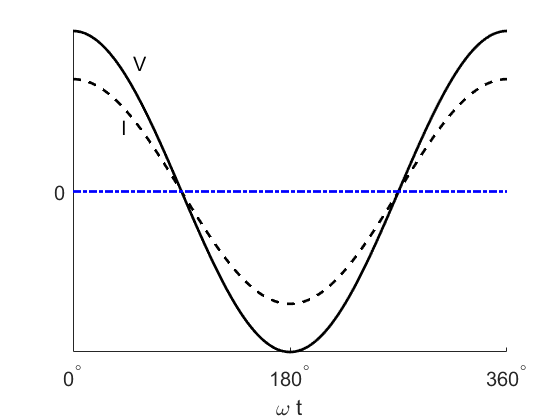

x = 0:1:360;
y1 = cosd(x);
y2 = cosd(x)*0.7;
plot(x,y1,'k-',x,y2,'k--',x,zeros(1,length(x)),'b-.','LineWidth',2);
xlabel('\omega t')
set(gca,'FontSize',15)
set(gca,'XTick',[0,180,360]);
set(gca,'XTicklabel',{'0^{\circ}','180^{\circ}','360^{\circ}'});
set(gca,'YTick',[0])
set(gca,'YTicklabel',{'0'})
text(50,0.8,'V','FontSize',15)
text(40,0.4,'I','FontSize',15)
axis tight
box off

fig 2.2

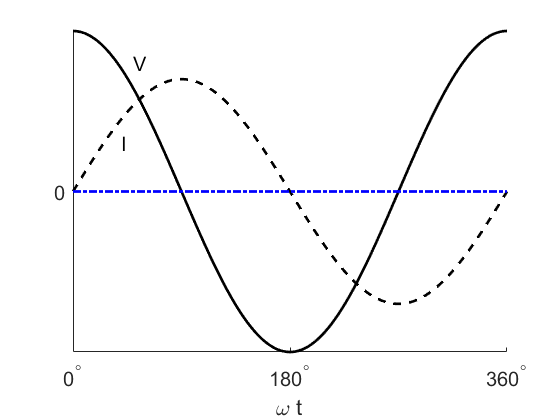

x = 0:1:360;
y1 = cosd(x);
y2 = cosd(x-90)*0.7;
plot(x,y1,'k-',x,y2,'k--',x,zeros(1,length(x)),'b-.','LineWidth',2);
xlabel('\omega t')
set(gca,'FontSize',15)
set(gca,'XTick',[0,180,360]);
set(gca,'XTicklabel',{'0^{\circ}','180^{\circ}','360^{\circ}'});
set(gca,'YTick',[0])
set(gca,'YTicklabel',{'0'})
text(50,0.8,'V','FontSize',15)
text(40,0.3,'I','FontSize',15)
axis tight
box off

fig 2.3

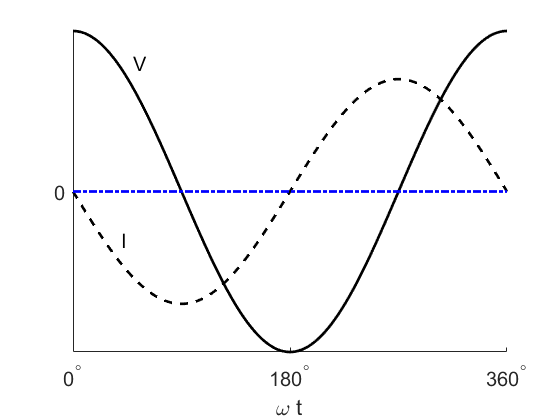

x = 0:1:360;
y1 = cosd(x);
y2 = cosd(x+90)*0.7;
plot(x,y1,'k-',x,y2,'k--',x,zeros(1,length(x)),'b-.','LineWidth',2);
xlabel('\omega t')
set(gca,'FontSize',15)
set(gca,'XTick',[0,180,360]);
set(gca,'XTicklabel',{'0^{\circ}','180^{\circ}','360^{\circ}'});
set(gca,'YTick',[0])
set(gca,'YTicklabel',{'0'})
text(50,0.8,'V','FontSize',15)
text(40,-0.3,'I','FontSize',15)
axis tight
box off

fig 2.8

clear all
close all
x = 0:1:360;
y1 = cosd(4*x);
y2 = cosd(4*x-30)*0.3;
y3 = y1.*y2;
y4 = 0.5*0.3*ones(1,length(x));
plot(x,y1,'k--',x,y2,'k-.',x,y3,'k-',x,y4,'b:','LineWidth',2);
xlabel('t')
set(gca,'FontSize',15)
set(gca,'XTick',[])
set(gca,'YTick',[])
text(20,0.9,'v(t)','FontSize',15)
hold on;plot([10,20],[0.8,0.85],'k')
text(80,-0.4,'i(t)','FontSize',15)
plot([50,80],[-0.3,-0.4],'k');plot([100,135],[-0.4,-0.3],'k')
text(100,4*max(abs(y3)),'p(t)=v(t)i(t)','FontSize',15);plot([135,135],[1.1*max(abs(y3)),3.5*max(abs(y3))],'k')
text(360,3*max(abs(y4)),'P_{av}','FontSize',15);plot([345,360],[max(abs(y4)),3*max(abs(y4))],'k')
axis tight
box off

fig 2.9

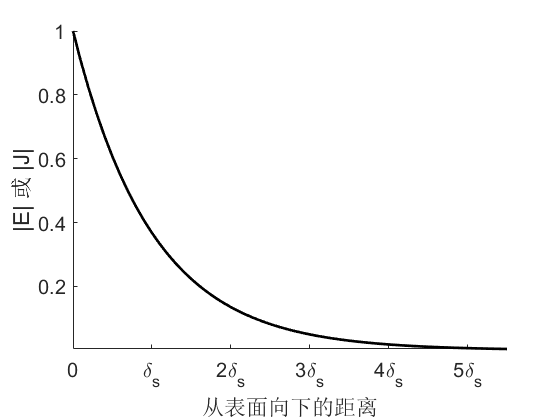

clear all
close all
z = 0:.1:5.5;
J = exp(-z);
plot(z,J,'k-','LineWidth',2)
set(gca,'FontSize',15)
set(gca,'XTick',[0,1,2,3,4,5]);
set(gca,'XTicklabel',{'0','\delta_s','2\delta_s','3\delta_s','4\delta_s','5\delta_s'})
xlabel('从表面向下的距离')
ylabel('|E| 或 |J|')
xlim([-0.3 5.5]);ylim([-0.1 1.1])
axis tight
box off

fig 4.20

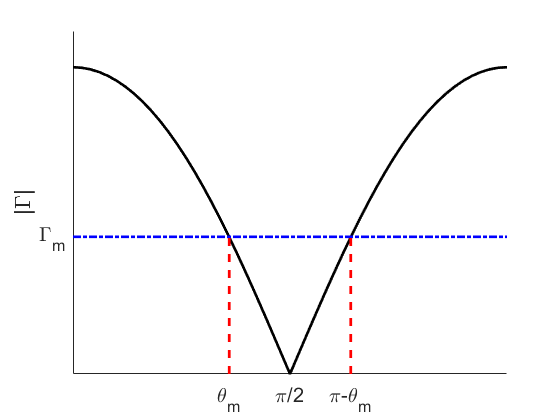

zl = 100+1i*50;
z0 = 50;
theta = 0:pi/50:pi;
absGamma = abs(1./sqrt(1+(4*z0*zl/(zl-z0)^2)*(sec(theta)).^2));
plot(theta,absGamma,'k-',theta,0.2*ones(1,length(theta)),'b-.','LineWidth',2);hold on
plot(ones(1,10)*1.13097,linspace(0,0.2,10),'r--',ones(1,10)*2.01062,linspace(0,0.2,10),'r--','LineWidth',2);
set(gca,'FontSize',15)
set(gca,'XTick',[1.13097,pi/2,2.01062]);
set(gca,'XTicklabel',{'\theta_m','\pi/2','\pi-\theta_m'})
set(gca,'YTick',[0.2]);
set(gca,'YTicklabel',{'\Gamma_m'})
ylabel('|\Gamma|')
box off